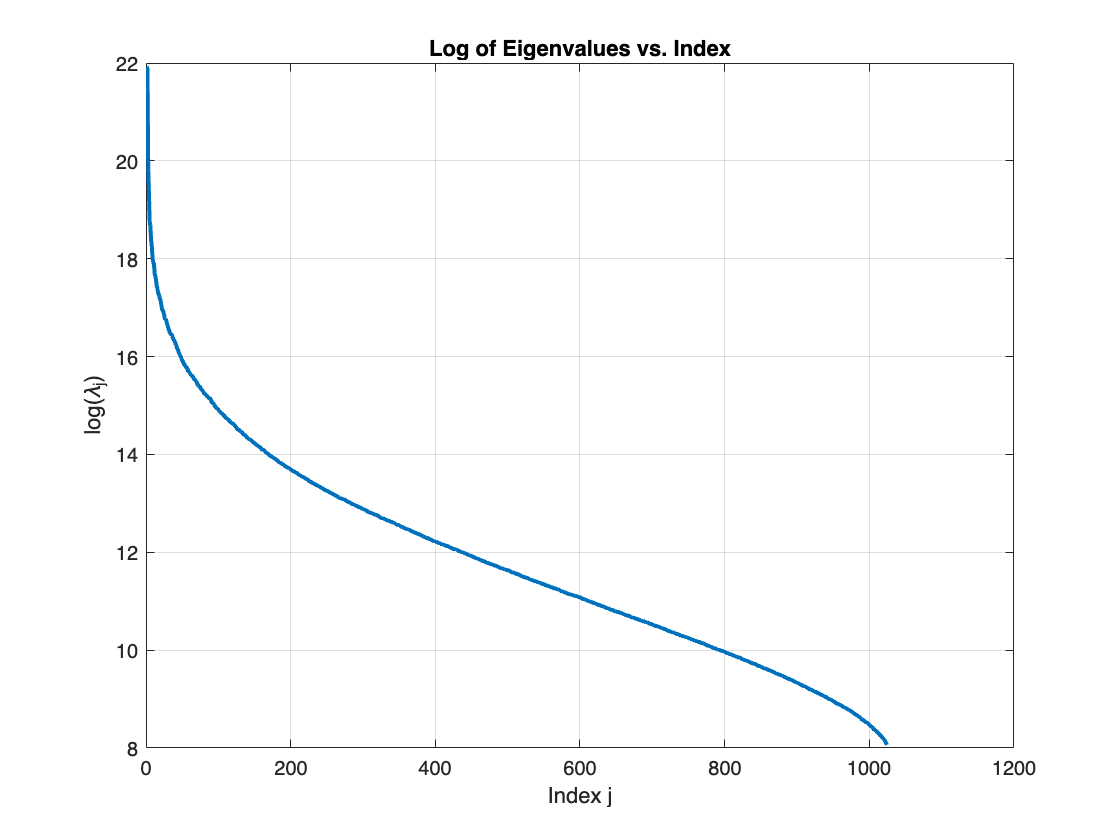

% 1a)

load('yalefaces.mat');

N = size(M, 3);   
d = 32 * 32;      

X = zeros(d, N);
for i = 1:N
    X(:, i) = reshape(M(:,:,i), d, 1);
end

mean_face = mean(X, 2);
X_centered = X - mean_face;
C = X_centered * X_centered';

% Using the eig function in MatLab
[eigenvectors, eigenvalues_matrix] = eig(C);
eigenvalues = diag(eigenvalues_matrix);

[eigenvalues_sorted, idx] = sort(eigenvalues, 'descend');
eigenvectors_sorted = eigenvectors(:, idx);


figure;
plot(log(eigenvalues_sorted), 'LineWidth', 2);
xlabel('Index j');
ylabel('log(\lambda_j)');
title('Log of Eigenvalues vs. Index');
grid on;

1a) C is a real, symmetric matrix, and the eigenvalues of these matrices are always real.

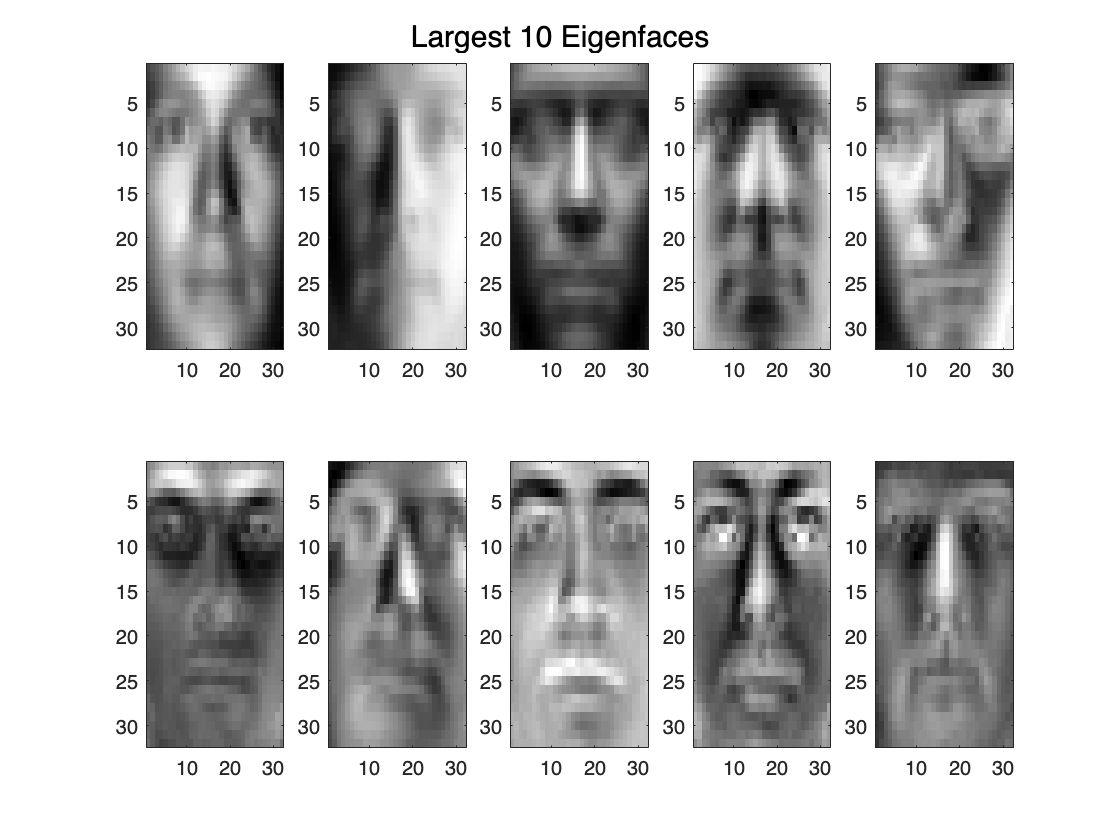

% 1b) 

% Made the images gray so easier to see the details, was blue and yellowish
% originally

% Top 10 largest eigenfaces
figure;
for i = 1:10
    eigenface = reshape(eigenvectors_sorted(:, i), [32, 32]);
    subplot(2, 5, i);
    imagesc(eigenface); colormap(gray);
end
sgtitle('Largest 10 Eigenfaces');

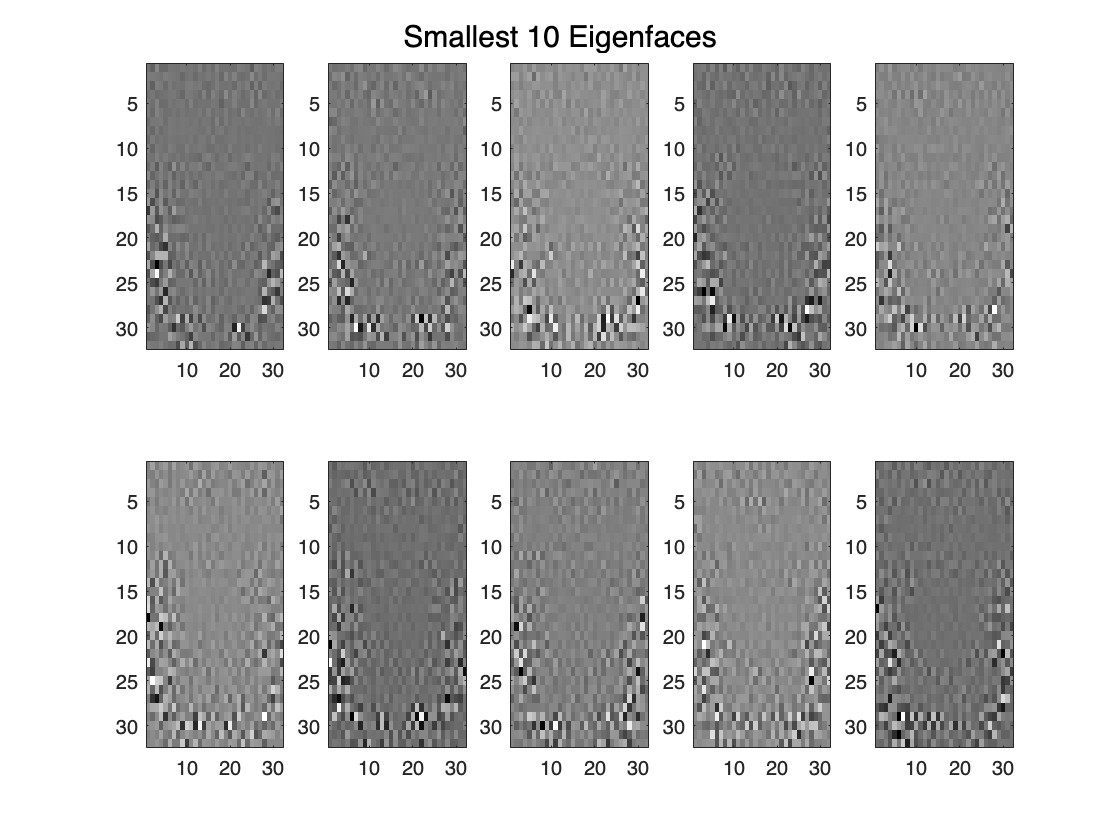


% Top 10 smallest eigenfaces
figure;
for i = 1:10
    eigenface = reshape(eigenvectors_sorted(:, end - i + 1), [32, 32]);
    subplot(2, 5, i);
    imagesc(eigenface); colormap(gray);
end
sgtitle('Smallest 10 Eigenfaces');

1b) The eigenfaces corresponding to the largest eigenvalues have decently high-level details that make up a face. They have abstract details like shading and actual face shapes. The eigenfaces of the lowest eigenvalues represent the low-level details of the faces, more specific details. You can think of it as a low-frequency vs high-frequency signals, thus these low eigenvalue eigenfaces have very "noisy" looking outputs (aka high frequency).

% 1c)

% Given values in the problem
image_indices = [1, 1076, 2043];
j_values = 2.^(1:10);

figure;

for img_idx = 1:length(image_indices)
    i = image_indices(img_idx);
    
    % Center the image by subtracting the mean face
    centered_image = X_centered(:, i);
    
    % Loop over j values to compute projection and reconstruction
    for j_idx = 1:length(j_values)
        j = j_values(j_idx);
        
        eigenvector_subset = eigenvectors_sorted(:, 1:j);
        
        projection = eigenvector_subset * (eigenvector_subset' * centered_image);
        
        reconstructed_image = projection + mean_face;
        
        % Reshape to 32x32 for visualization
        reconstructed_image_reshaped = reshape(reconstructed_image, [32, 32]);
        
        % Plot
        subplot(length(image_indices), length(j_values), (img_idx - 1) * length(j_values) + j_idx);
        imagesc(reconstructed_image_reshaped); colormap(gray);
        axis off;
    end
end

sgtitle('Reconstructed Images');

%1d)

% Given sets of indices
I1 = [1, 2, 7];
I2 = [2043, 2044, 2045];
combined_indices = [I1, I2];

% Number of eigenvectors to use
j = 25; 
B = eigenvectors_sorted(:, 1:j);


c = zeros(j, length(I1) + length(I2));

% Project the centered images onto the eigenvectors
for idx = 1:length(I1)
    % First person
    i = I1(idx);
    c(:, idx) = B' * (X(:, i) - mean_face);
end

for idx = 1:length(I2)
    % Second person
    i = I2(idx);
    c(:, length(I1) + idx) = B' * (X(:, i) - mean_face);
end

% Compute pairwise Euclidean distances
distances = pdist(c', 'euclidean');
distances_matrix = squareform(distances);
disp(distances_matrix);

   1.0e+03 *

         0    0.5928    0.4724    1.0826    1.5278    1.3660
    0.5928         0    0.3922    1.4038    1.9028    1.6124
    0.4724    0.3922         0    1.2640    1.7907    1.5789
    1.0826    1.4038    1.2640         0    0.7588    0.6812
    1.5278    1.9028    1.7907    0.7588         0    0.8284
    1.3660    1.6124    1.5789    0.6812    0.8284         0



1d) The pairwise distances in the top left of the table (the first 3 rows and coloumns) are calculated for the images of the same person (ie. first person). The values in the bottom right of the table (last 3 rows and columns) are calculated on the images for the other person (ie. just the second person). All the other values are pairwise distances calculated between the images of the 2 different people (ie. betwee the first and second person). As you can see, distances between the images of 2 different people are significantly higher than distances between the images of the same person. You can use this attribute to create a face recognition scheme by comparing the pairwise distances.

export("Application2.mlx")

ans = '/Users/raiyannjacob/Desktop/ECE367/PSET3/Application2.pdf'